# MA 493 Project 2: Sensitivities Analysis

`Authored: Sarah Bird (The Do-er), Nicholas Gawron (Group Parent), Jamie Loring (The Facilitator), Andrea Stancescu (The Caffeinated)`

## Part 1

Clear the workspace

clear all
close all

Set the final time 

tFinal = 8;

Set the step size in the forward difference approximation (5)

h = 0.1;

Create the time vector with interval size h

t = [0:h:tFinal];

Set the nominal values of the parameters

mNom = 1;
kNom = 1;
cNom = 2.3;
ANom = 0.1;
%thetaNom = [mNom,kNom,cNom,ANom];

p(1) = mNom;
p(2) = cNom;
p(3) = kNom;

Set the value of the perturbation for computing scaled sensitivities

alpha = 0.1;

options = odeset('AbsTol',1e-9, 'RelTol', 1e-8); 

Specify the model to be solved - see below for function definition

modelRHS = @(t,y)(Damped(t,y,p));

Solve the ODE system, numerically, using "ode45"

[t,y] = ode45(modelRHS, t, [ANom 0], options);

Extract the relevant solutions

disp = y(:,1);
vel = y(:,2);

Evaluate and plot the response at the nominal values

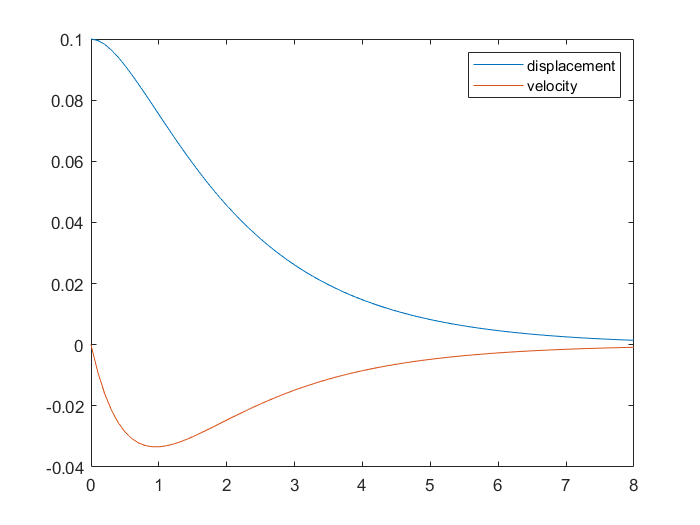

figure(1)
plot(t,y);
legend("displacement", "velocity")

### Calculating Normal Sensitivities and Forward Distance Sensitivities

Calculate the sensitivities via the forward difference rule (5)

modelRHS1 = @(t,y)(Damped(t,y,p+[h,0,0]));
[t1,y1] = ode45(modelRHS1, t, [ANom 0], options);
s1 = (y1(:,1) - disp)/h;
scaleds1 = 2*alpha*mNom*(y1(:,1) - disp)/h;


modelRHS2 = @(t,y)(Damped(t,y,p+[0,h,0]));
[t2,y2] = ode45(modelRHS2, t, [ANom 0], options);
s2 = (y2(:,1) - disp)/h;
scaleds2 = 2*alpha*kNom*(y2(:,1) - disp)/h;


modelRHS3 = @(t,y)(Damped(t,y,p+[0,0,h]));
[t3,y3] = ode45(modelRHS3, t, [ANom 0], options);
s3 = (y3(:,1) - disp)/h;
scaleds3 = 2*alpha*cNom*(y3(:,1) - disp)/h;

Plot the normal sensitivities

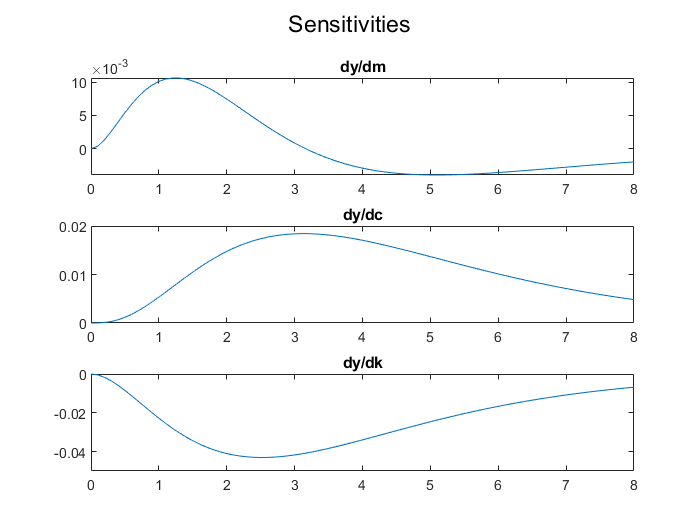

figure(2)
subplot(3,1,1)
plot(t1,s1);
title('dy/dm')
hold on
subplot(3,1,2);
plot(t2,s2);
title('dy/dc')
hold on
subplot(3,1,3);
plot(t3,s3);
title('dy/dk')
sgtitle("Sensitivities")

Plot the scaled sensitivities

figure(3)
subplot(3,1,1)
plot(t1,scaleds1);
title('dy/dm')
hold on
subplot(3,1,2);
plot(t2,scaleds2);
title('dy/dc')
hold on
subplot(3,1,3);
plot(t3,scaleds3);
title('dy/dk')
sgtitle("Scaled Sensitivities - forward difference approximation")

### Calculating Centered Difference Sensitivities

Calculate the sensitivities via the centered difference rule (5)

modelRHS1 = @(t,y)(Damped(t,y,p+[h,0,0]));
[t1,y11] = ode45(modelRHS1, t, [ANom 0], options);
modelRHS1 = @(t,y)(Damped(t,y,p-[h,0,0]));
[t1,y12] = ode45(modelRHS1, t, [ANom 0], options);
s1 = (y11(:,1) - y12(:,1))/(2*h);
scaleds1 = 2*alpha*mNom*(y11(:,1) - y12(:,1))/(2*h);


modelRHS2 = @(t,y)(Damped(t,y,p+[0,h,0]));
[t2,y21] = ode45(modelRHS2, t, [ANom 0], options);
modelRHS2 = @(t,y)(Damped(t,y,p-[0,h,0]));
[t2,y22] = ode45(modelRHS2, t, [ANom 0], options);
s2 = (y21(:,1) - y22(:,1))/(2*h);
scaleds2 = 2*alpha*cNom*(y21(:,1) - y22(:,1))/(2*h);


modelRHS3 = @(t,y)(Damped(t,y,p+[0,0,h]));
[t3,y31] = ode45(modelRHS3, t, [ANom 0], options);
modelRHS3 = @(t,y)(Damped(t,y,p-[0,0,h]));
[t3,y32] = ode45(modelRHS3, t, [ANom 0], options);
s3 = (y31(:,1) - y32(:,1))/(2*h);
scaleds3 = 2*alpha*kNom*(y31(:,1) - y32(:,1))/(2*h);

Plot the centered difference scaled sensitivities

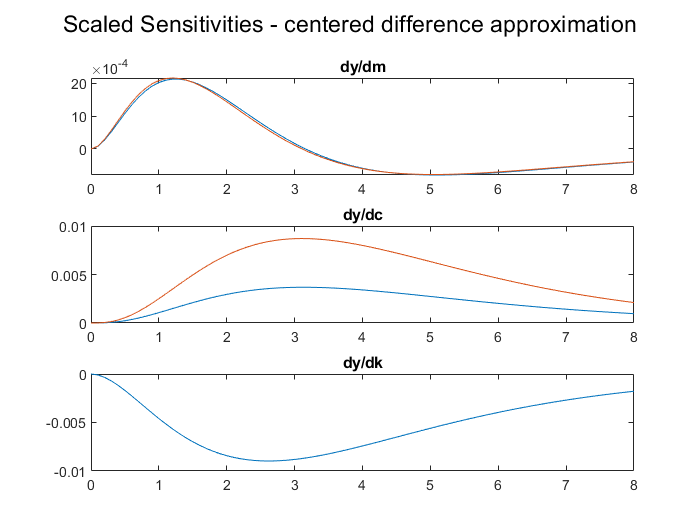

figure(3)
subplot(3,1,1)
plot(t1,scaleds1);
title('dy/dm')
hold on
subplot(3,1,2);
plot(t2,scaleds2);
title('dy/dc')
hold on
subplot(3,1,3);
plot(t3,scaleds3);
title('dy/dk')
sgtitle("Scaled Sensitivities - centered difference approximation")

### Lastly, compute the sensitivity matrix at the 4 indicated data points

Normal sensitivity matrix

Here, we have 4 data points (rows) and 3 parameters (columns)

S = zeros(4,3);

Store the time values where data is collected

tData = [2 4 6 8];

Compute the senstivity matrix based on forward differences

dyData = @(t,y)(Damped(tData,y,p));
[t,yData] = ode45(dyData, tData, [ANom 0], options);

S1 = @(t,y)(Damped(tData,y,p+[h,0,0]));
[t1,y1Data] = ode45(S1, tData, [ANom 0], options);
S(:,1) = (y1Data(:,1) - yData(:,1))/h;
% scaled - S(:,1) = 2*alpha*mNom*(fOD(tData,thetaNom+[h,0,0,0])-yData)/h;

S2 = @(t,y)(Damped(tData,y,p+[0,h,0]));
[t2,y2Data] = ode45(S2, tData, [ANom 0], options);
S(:,2) = (y2Data(:,1) - yData(:,1))/h;
% scaled - S(:,2) = 2*alpha*kNom*(fOD(tData,thetaNom+[0,h,0,0])-yData)/h;

S3 = @(t,y)(Damped(tData,y,p+[0,0,h]));
[t1,y3Data] = ode45(S3, tData, [ANom 0], options);
S(:,3) = (y3Data(:,1) - yData(:,1))/h;
% scaled - S(:,3) = 2*alpha*cNom*(fOD(tData,thetaNom+[0,0,h,0])-yData)/h;

S

S =          0         0         0
    0.0075    0.0148   -0.0410
   -0.0029    0.0171   -0.0339
   -0.0036    0.0101   -0.0167


#### Forward Distance Scaled Sensitivity Matrix

Here, we have 4 data points (rows) and 3 parameters (columns)

SScaled = zeros(4,3);

Store the time values where data is collected

tData = [2 4 6 8];

Compute the senstivity matrix based on forward differences

dyData = @(t,y)(Damped(tData,y,p));
[t,yData] = ode45(dyData, tData, [ANom 0], options);

S1 = @(t,y)(Damped(tData,y,p+[h,0,0]));
[t1,y1Data] = ode45(S1, tData, [ANom 0], options);
SScaled(:,1) = 2*alpha*mNom*(y1Data(:,1) - yData(:,1))/h;
% scaled - S(:,1) = 2*alpha*mNom*(fOD(tData,thetaNom+[h,0,0,0])-yData)/h;

S2 = @(t,y)(Damped(tData,y,p+[0,h,0]));
[t2,y2Data] = ode45(S2, tData, [ANom 0], options);
SScaled(:,2) = 2*alpha*cNom*(y2Data(:,1) - yData(:,1))/h;
% scaled - S(:,2) = 2*alpha*kNom*(fOD(tData,thetaNom+[0,h,0,0])-yData)/h;

S3 = @(t,y)(Damped(tData,y,p+[0,0,h]));
[t1,y3Data] = ode45(S3, tData, [ANom 0], options);
SScaled(:,3) = 2*alpha*kNom*(y3Data(:,1) - yData(:,1))/h;
% scaled - S(:,3) = 2*alpha*cNom*(fOD(tData,thetaNom+[0,0,h,0])-yData)/h;

SScaledForward = SScaled

SScaledForward =          0         0         0
    0.0015    0.0068   -0.0082
   -0.0006    0.0078   -0.0068
   -0.0007    0.0047   -0.0033


#### Centered Difference Scaled Sensitivity Matrix

SScaled = zeros(4,3);

Store the time values where data is collected

tData = [2 4 6 8];

Compute the senstivity matrix based on forward differences

dyData = @(t,y)(Damped(tData,y,p));
[t,yData] = ode45(dyData, tData, [ANom 0], options);


S11 = @(t,y)(Damped(tData,y,p+[h,0,0]));
[t1,y11] = ode45(S11, tData, [ANom 0], options);

S12 = @(t,y)(Damped(tData,y,p-[h,0,0]));
[t1,y12] = ode45(S12, tData, [ANom 0], options);

SScaled(:,1) = 2*alpha*mNom*(y11(:,1) - y12(:,1))/(2*h);



S21 = @(t,y)(Damped(tData,y,p+[0,h,0]));
[t2,y21] = ode45(S21, tData, [ANom 0], options);

S22 = @(t,y)(Damped(tData,y,p-[0,h,0]));
[t2,y22] = ode45(S22, tData, [ANom 0], options);

SScaled(:,2) = 2*alpha*cNom*(y21(:,1) - y22(:,1))/(2*h);



S31 = @(t,y)(Damped(tData,y,p+[0,0,h]));
[t3,y31] = ode45(S31, tData, [ANom 0], options);

S32 = @(t,y)(Damped(tData,y,p-[0,0,h]));
[t3,y32] = ode45(S32, tData, [ANom 0], options);

SScaled(:,3) = 2*alpha*kNom*(y31(:,1) - y32(:,1))/(2*h);




SScaledCentered = SScaled

SScaledCentered =          0         0         0
    0.0014    0.0070   -0.0084
   -0.0006    0.0080   -0.0074
   -0.0007    0.0046   -0.0040


## Part 2: SEIR Model

### Part A

#### Explain the significance of each term on the right hand side of equations (3-6) 

- Equation 3:

- Equation 4:

- Equation 5:

- Equation 6: This is the rate 

% k(1)*S*I = infection rate

% k(2)*E = exposure rate ??

% k(3)*I = recovery rate 

% initial conditions - we are modeling a situation where the disease has

% just been introduced so no one has recovered from the disease (R(0) = 0), 

% however, there are S0 people susceptible, E0 people exposed and I0 people

% already infected.

### Part B

Clear the workspace

clear all
close all

Set the final time

tFinal =100;

Set the step size in the forward difference approximation (5)

h = 0.1;

Create the time vector with interval size h

t = [0:h:tFinal];

Set the nominal values of the parameters

k1 = 1e-5;
k2 = 0.03;
k3 = 0.01;


p(1) = k1;
p(2) = k2;
p(3) = k3;

Set initial conditions

S0 = 1e6; % 1 million susceptible individuals
E0 = 0;
I0 = 1000; % 0.1% of the population is 1000 individuals
R0 = 0;
ic = [S0 E0 I0 R0];

Set the value of the perturbation for computing scaled sensitivities

alpha = 0.1;

options = odeset('AbsTol',1e-9, 'RelTol', 1e-8); 

Specify the model to be solved - see below for function definition

modelRHS = @(t,y)(seir(t,y,p));

Solve the ODE system, numerically, using "ode45"

[t,y] = ode45(modelRHS, t, ic, options);

Extract the relevant solutions

s = y(:,1);
e = y(:,2);
i = y(:,3);
r =y(:,4);

Evaluate and plot the response at the nominal values

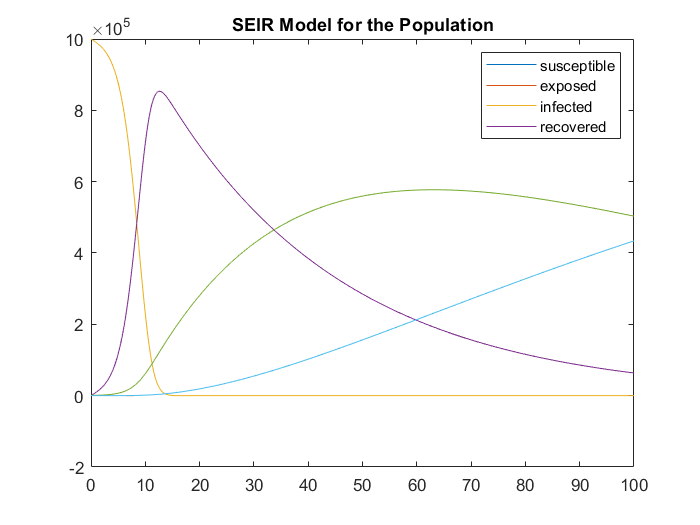

figure(1)
hold on
plot(t,s)
plot(t,e)
plot(t,i)
plot(t,r)
hold off
title("SEIR Model for the Population")
legend("susceptible", "exposed", "infected", "recovered")

#### Forward Difference Rule

Calculate the sensitivities via the forward difference rule (5)

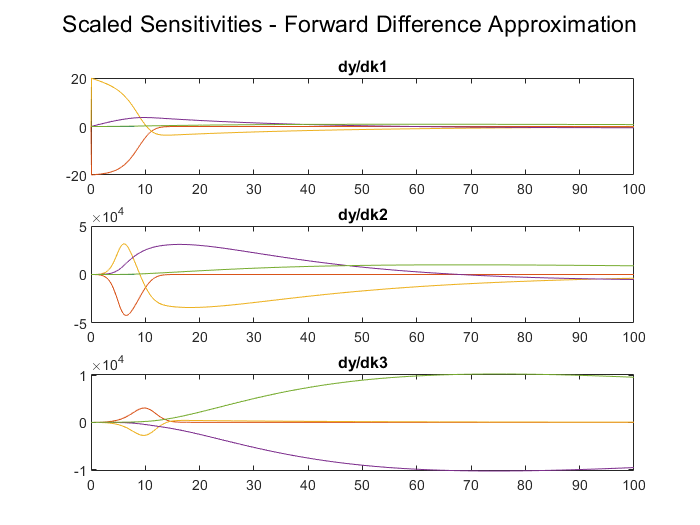

figure(2)

modelRHS1 = @(t,y)(seir(t,y,p+[h,0,0]));
[t1,y1] = ode45(modelRHS1, t, ic, options);
scaleds1s = 2*alpha*k1*(y1(:,1) - s) /h;
scaleds1e = 2*alpha*k1*(y1(:,2) - e) /h;
scaleds1i = 2*alpha*k1*(y1(:,3) - i) /h;
scaleds1r = 2*alpha*k1*(y1(:,4) - r) /h;
subplot(3, 1, 1)
hold on
plot(t1, scaleds1s)
plot(t1, scaleds1e)
plot(t1, scaleds1i)
plot(t1, scaleds1r)
hold off
title('dy/dk1')


modelRHS2 = @(t,y)(seir(t,y,p+[0,h,0]));
[t2,y2] = ode45(modelRHS2, t, ic, options);
scaleds2s = 2*alpha*k2*(y2(:,1) - s) /h;
scaleds2e = 2*alpha*k2*(y2(:,2) - e) /h;
scaleds2i = 2*alpha*k2*(y2(:,3) - i) /h;
scaleds2r = 2*alpha*k2*(y2(:,4) - r) /h;
subplot(3, 1, 2)
hold on
plot(t2, scaleds2s)
plot(t2, scaleds2e)
plot(t2, scaleds2i)
plot(t2, scaleds2r)
hold off
title('dy/dk2')


modelRHS3 = @(t,y)(seir(t,y,p+[0,0,h]));
[t3,y3] = ode45(modelRHS3, t, ic, options);
scaleds3s = 2*alpha*k3*(y3(:,1) - s) /h;
scaleds3e = 2*alpha*k3*(y3(:,2) - e) /h;
scaleds3i = 2*alpha*k3*(y3(:,3) - i) /h;
scaleds3r = 2*alpha*k3*(y3(:,4) - r) /h;
subplot(3, 1, 3)
hold on
plot(t3, scaleds3s)
plot(t3, scaleds3e)
plot(t3, scaleds3i)
plot(t3, scaleds3r)
hold off
title('dy/dk3')

sgtitle("Scaled Sensitivities - Forward Difference Approximation")

#### Scaled Sensitivity Matrix 

Lastly, compute the SCALED sensitivity matrix at the 4 indicated data points

Here, we have 4 data points (rows) and 3 parameters (columns)

SSScaled = zeros(4,3);
SEScaled = zeros(4,3);
SIScaled = zeros(4,3);
SRScaled = zeros(4,3);

Store the time values where data is collected

tData = [20 40 60 80];

Compute the senstivity matrix based on forward differences

dyData = @(t,y)(seir(tData,y,p));
[t,yData] = ode45(dyData, tData, ic, options);
s = yData(:,1);
e = yData(:,2);
i  = yData(:,3);
r = yData(:,4);


S1 = @(t,y)(seir(tData,y,p+[h,0,0]));
[t1,y1Data] = ode45(S1, tData, ic, options);
SSScaled(:,1) = 2*alpha*k1*(y1Data(:,1) - s) /h;
SEScaled(:,1) = 2*alpha*k1*(y1Data(:,2) - e) /h;
SIScaled(:,1) = 2*alpha*k1*(y1Data(:,3) - i) /h;
SRScaled(:,1) = 2*alpha*k1*(y1Data(:,4) - r) /h;



S2 = @(t,y)(seir(tData,y,p+[0,h,0]));
[t2,y2Data] = ode45(S2, tData, ic, options);
SSScaled(:,2) = 2*alpha*k2*(y2Data(:,1) - s) /h;
SEScaled(:,2) = 2*alpha*k2*(y2Data(:,2) - e) /h;
SIScaled(:,2) = 2*alpha*k2*(y2Data(:,3) - i) /h;
SRScaled(:,2) = 2*alpha*k2*(y2Data(:,4) - r) /h;



S3 = @(t,y)(seir(tData,y,p+[0,0,h]));
[t1,y3Data] = ode45(S3, tData, ic, options);
SSScaled(:,3) = 2*alpha*k3*(y3Data(:,1) - s) /h;
SEScaled(:,3) = 2*alpha*k3*(y3Data(:,2) - e) /h;
SIScaled(:,3) = 2*alpha*k3*(y3Data(:,3) - i) /h;
SRScaled(:,3) = 2*alpha*k3*(y3Data(:,4) - r) /h;



SSScaled

SSScaled =          0         0         0
   -0.0000   -0.0003    0.1884
   -0.0000   -0.0000   -0.0000
    0.0000    0.0000   -0.0000


SEScaled

SEScaled = 	1.0e+04 *

         0         0         0
   -0.0003   -3.3842    0.0381
   -0.0002   -2.2472    0.0209
   -0.0001   -1.2622    0.0115


SIScaled

SIScaled = 	1.0e+04 *

         0         0         0
    0.0002    3.0018   -0.2546
    0.0001    1.4174   -0.7571
   -0.0000    0.2751   -0.9931


SRScaled

SRScaled = 	1.0e+03 *

         0         0         0
    0.0005    3.8245    2.1645
    0.0009    8.2977    7.3615
    0.0009    9.8708    9.8162


## Bonus

## Conclusions

## Functions

% Functon "Damped"
%
% Implements ODE model for damped oscillatory motion of a
% mass-spring-dashpot system

% Inputs:
%   t - time
%   y - state variables (displacement and velocity)
%   p - vector of model parameters [m c k]
% Output:
%   dy/dt

function dy = Damped(t, y, p)
  dy = [0; 0];
  m = p(1);
  c = p(2);
  k = p(3);

  dy(1) = y(2);
  dy(2) = -k/m * y(1) - c/m * y(2);

end

% Functon "seir"
%
% Implements ODE model for damped oscillatory motion of a
% mass-spring-dashpot system

% Inputs:
%   t - time
%   y - [S(t) ; E(t); I(t); R(t)]
%   p - vector of model parameters [k1 k2 k3]
% Output:
%   dy/dt 

function dy = seir(t, y, p)
  dy = [0; 0; 0; 0];
  k1 = p(1);
  k2 = p(2);
  k3 = p(3);

  dy(1) = -k1 * y(1)* y(3);
  dy(2) = (k1 * y(1)* y(3)) - (k2*y(2));
  dy(3) = (k2*y(2)) - (k3*y(3));
  dy(4) = k3*y(3) ;

end